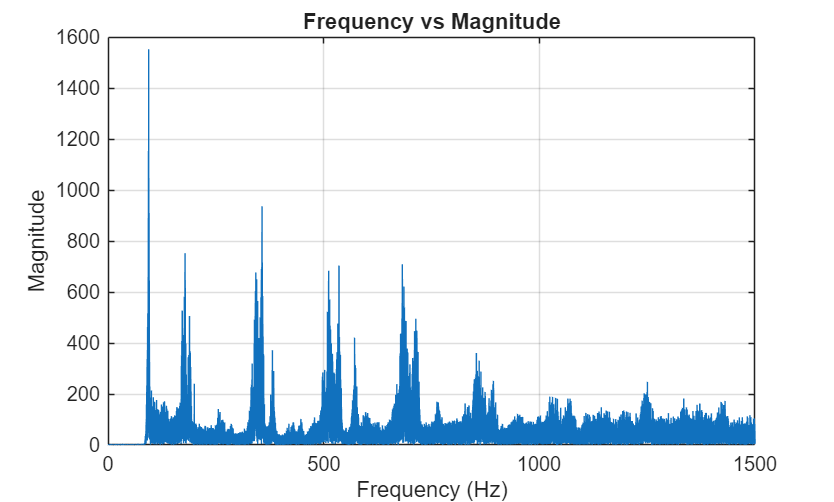

% Load the audio file
[x, fs] = audioread('Acoustics_system\Dataset_DronePoint\DS1\ExperimentallyCollected\Mavic_Test_File2.wav');

% Design a bandpass filter
fpass = [100 2500]; % Passband frequencies
y = bandpass(x, fpass, fs); % Apply bandpass filter

% Perform FFT
nfft = 2^nextpow2(length(y)); % Next power of 2 from length of y
Y = fft(y, nfft); % Compute FFT
f = fs*(0:(nfft/2))/nfft; % Frequency vector

% Compute magnitude
magnitude = abs(Y(1:nfft/2+1));

% Plot frequency vs magnitude
figure;
plot(f, magnitude);
xlim([0 1500])
title('Frequency vs Magnitude');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

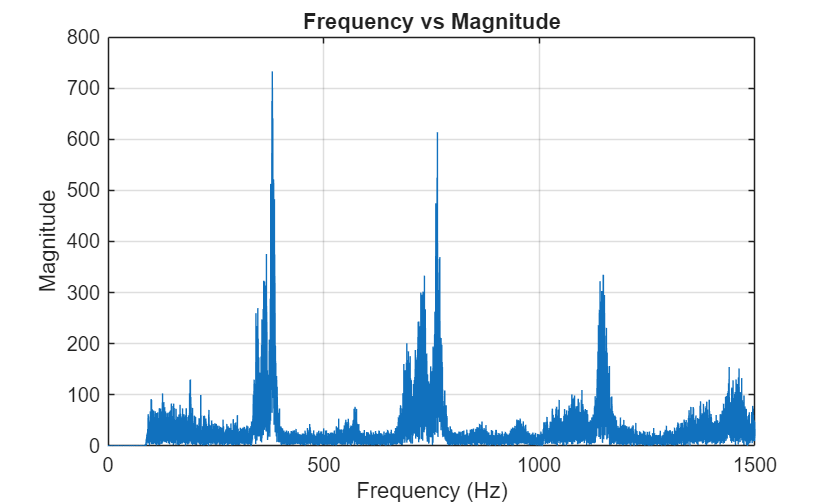

% Load the audio file
%[x, fs] = audioread('Acoustics_system\Dataset_DronePoint\DS1\ExperimentallyCollected\Mavic_Test_File2.wav');
%[x, fs] = audioread('Acoustics_system\Dataset_DronePoint\DS1\ExperimentallyCollected\Phantom_Test_File1.wav');
[x, fs] = audioread('Acoustics_system\Dataset_DronePoint\DS1\ExperimentallyCollected\Spark_Test_File3.wav');

% Design a bandpass filter
fpass = [100 2500]; % Passband frequencies
y = bandpass(x, fpass, fs); % Apply bandpass filter

% Perform FFT
nfft = 2^nextpow2(length(y)); % Next power of 2 from length of y
Y = fft(y, nfft); % Compute FFT
f = fs*(0:(nfft/2))/nfft; % Frequency vector

% Compute magnitude
magnitude = abs(Y(1:nfft/2+1));

% Plot frequency vs magnitude
figure;
plot(f, magnitude);
xlim([0 1500])
title('Frequency vs Magnitude');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

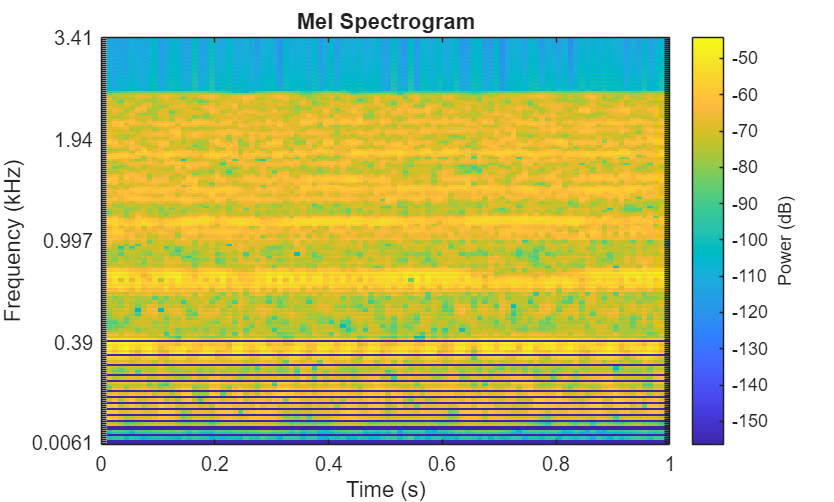


% Compute and plot Mel spectrogram
figure;
melSpectrogram(y, fs, 'NumBands', 400, 'FFTLength', 2048);
xlim([0 1])
ylim([0 2])
title('Mel Spectrogram');
xlabel('Time (s)');
ylabel('Frequency (Mel)');

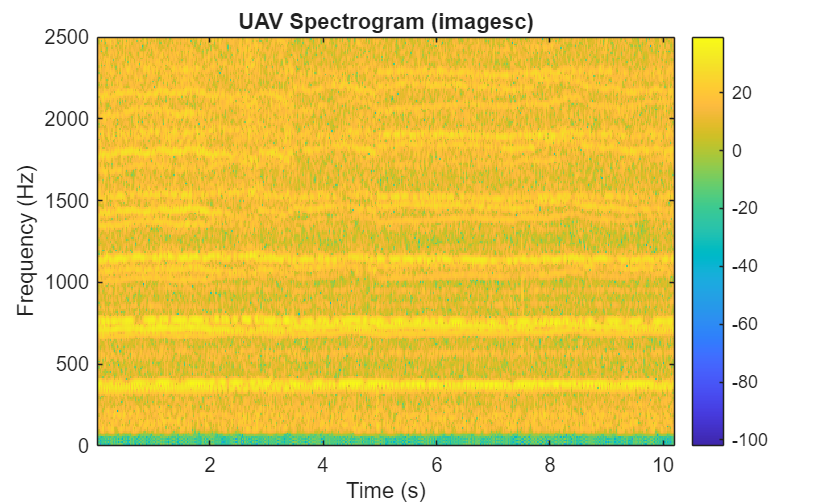


% Load the audio file
%[x, fs] = audioread('Acoustics_system\Dataset_DronePoint\DS1\ExperimentallyCollected\Phantom_Test_File1.wav');
%[x, fs] = audioread('Acoustics_system\Dataset_DronePoint\DS2\Experimentally Collected Data\CalmEnvironment_Test.wav');
[x, fs] = audioread('Acoustics_system\Dataset_DronePoint\DS1\ExperimentallyCollected\Spark_Test_File3.wav');

% Convert to mono and normalize
x = mean(x, 2); % Mono
x = x / max(abs(x)); % Normalize

% Bandpass filter to isolate UAV-relevant frequencies
fpass = [100 2500]; % Typical UAV rotor band
y = bandpass(x, fpass, fs);

% STFT parameters
windowLength = 2048;
overlapLength = 1024;
fftLength = 4096;

% Compute STFT on filtered signal
[s, f, t] = stft(y, fs, 'Window', hamming(windowLength), ...
                 'OverlapLength', overlapLength, ...
                 'FFTLength', fftLength);

% Convert to dB scale
S_dB = 10*log10(abs(s).^2);

% Plot using imagesc
figure;
imagesc(t, f, S_dB);
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
ylim([-0 0.25]*10^4)
title('UAV Spectrogram (imagesc)');
colorbar;

% Overlay known UAV frequency bands (example: Phantom ~500 Hz fundamental)
hold on;

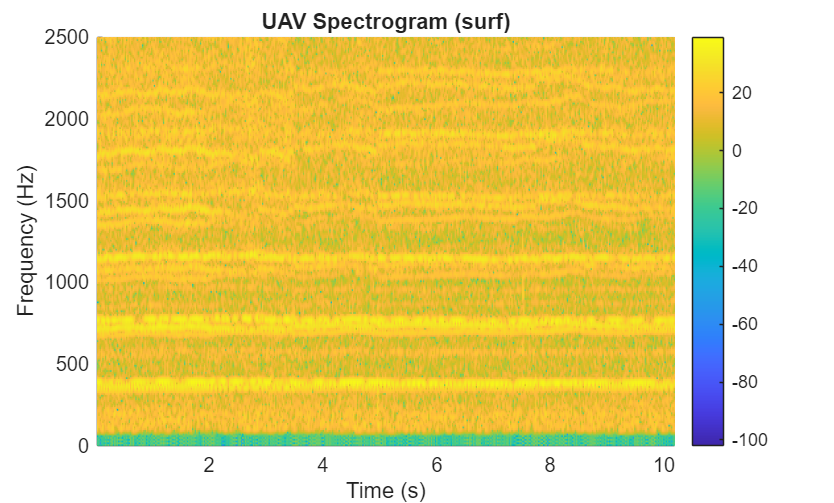

%plot(t, 500*ones(size(t)), 'r--', 'LineWidth', 1.5); % Fundamental
%plot(t, 1000*ones(size(t)), 'g--', 'LineWidth', 1.5); % 2nd harmonic
%plot(t, 1500*ones(size(t)), 'b--', 'LineWidth', 1.5); % 3rd harmonic
%legend('500 Hz', '1000 Hz', '1500 Hz');

% Plot using surf
figure;
surf(t, f, S_dB, 'EdgeColor', 'none');
axis tight;
view(0, 90); % Top-down view
xlabel('Time (s)');
ylabel('Frequency (Hz)');
ylim([-0 0.25]*10^4)
title('UAV Spectrogram (surf)');
colorbar;

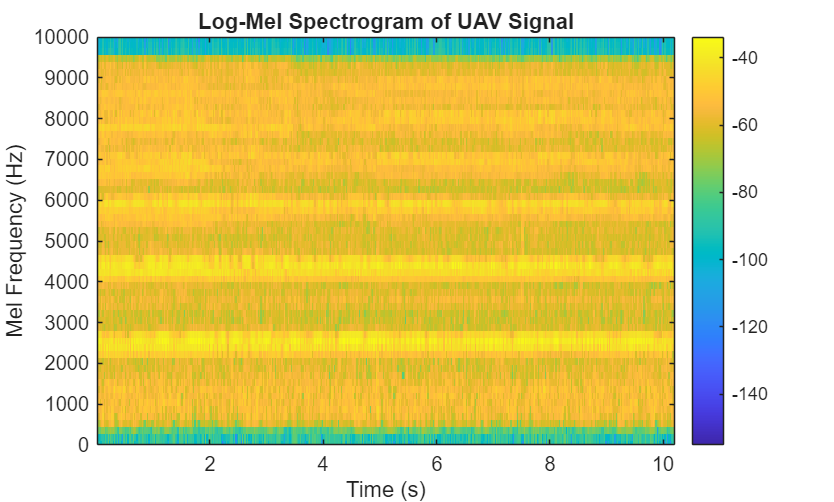


% Compute Log-Mel Spectrogram
figure;
[melS, melF, melT] = melSpectrogram(y, fs, ...
    'NumBands', 128, ...
    'FFTLength', 2048, ...
    'Window', hamming(2048), ...
    'OverlapLength', 1024);

% Convert to log scale (dB)
melS_dB = 10*log10(melS + eps); % eps avoids log(0)

% Plot with imagesc
imagesc(melT, melF, melS_dB);
axis xy;
xlabel('Time (s)');
ylabel('Mel Frequency (Hz)');
ylim([0 1]*10^4);
title('Log-Mel Spectrogram of UAV Signal');
colorbar;

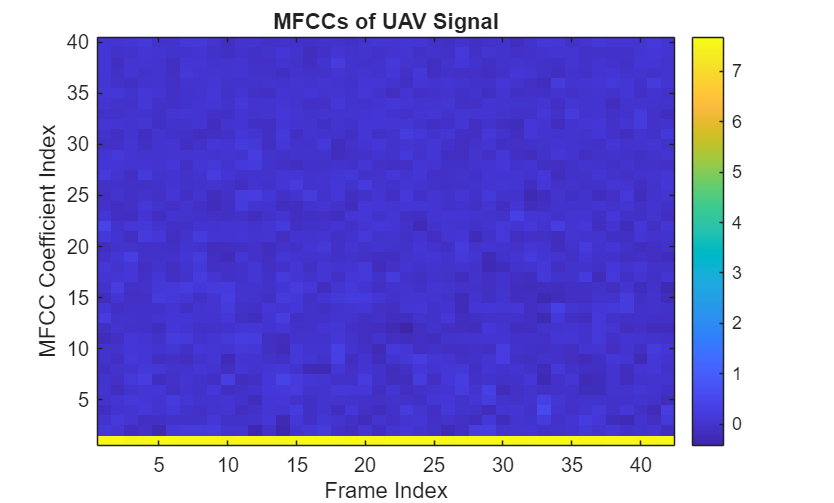



% Compute MFCCs from the bandpass-filtered signal
fs = 44100; % Sample rate (replace with your actual sample rate)
y = randn(fs, 1); % Example signal (replace with your actual signal)

% Define parameters
windowLength = 2048; % Length of the window
overlapLength = 1024; % Overlap length
fftLength = 2048; % FFT length

% Compute MFCCs from the bandpass-filtered signal
coeffs = mfcc(y, fs, ...
    'Window', hamming(windowLength, 'periodic'), ...
    'OverlapLength', overlapLength, ...
    'FFTLength', fftLength, ...
    'NumCoeffs', 40, ...
    'LogEnergy', 'Replace');


% Plot MFCCs
figure;
imagesc(coeffs');
axis xy;
xlabel('Frame Index');
ylabel('MFCC Coefficient Index');
title('MFCCs of UAV Signal');
colorbar;

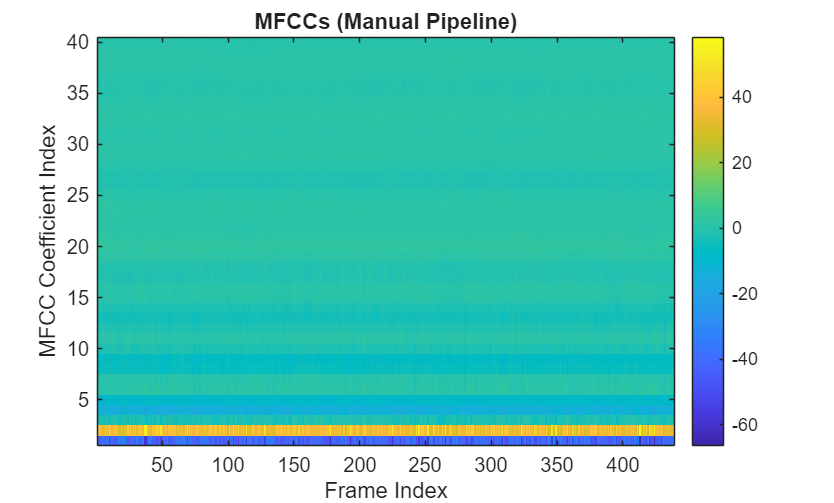



% Parameters
fs = 44100;
windowLength = 2048;
overlapLength = 1024;
fftLength = 2048;
numMelBands = 40;
numCoeffs = 40;

% Preprocessing
x = mean(x, 2); % Mono
x = x / max(abs(x)); % Normalize
y = bandpass(x, [250 2500], fs); % Bandpass filter
% Framing
win = hamming(windowLength, 'periodic');
[S, ~] = buffer(y, windowLength, overlapLength, 'nodelay');
numFrames = size(S, 2);

% Initialize MFCC matrix
mfccs = zeros(numCoeffs, numFrames);

% Mel filter bank
melFB = designAuditoryFilterBank(fs, 'FFTLength', fftLength, 'NumBands', numMelBands);

for i = 1:numFrames
    frame = S(:, i) .* win;
    spectrum = abs(fft(frame, fftLength)).^2;
    melEnergies = melFB * spectrum(1:fftLength/2+1); % Apply Mel filters
    logMel = log(melEnergies + eps); % Log compression
    mfccs(:, i) = dct(logMel); % DCT to get MFCCs
end
% Plot MFCCs
figure;
imagesc(mfccs);
axis xy;
xlabel('Frame Index');
ylabel('MFCC Coefficient Index');
title('MFCCs (Manual Pipeline)');
colorbar;

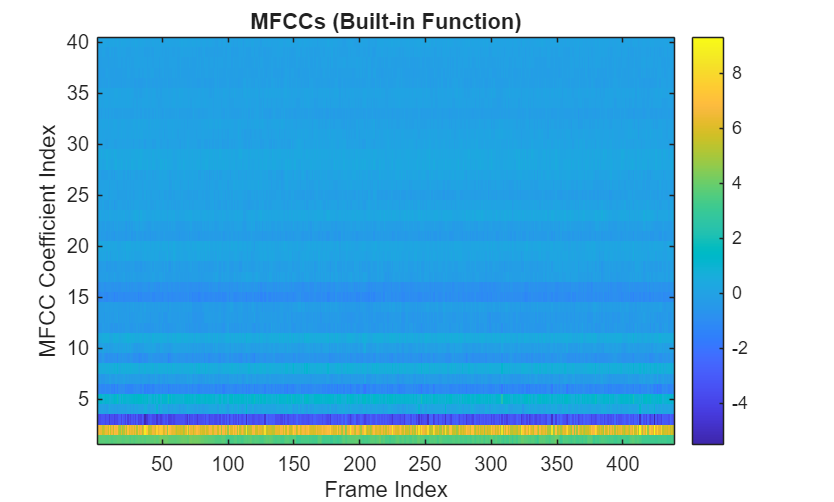


% Parameters
windowLength = 2048;
overlapLength = 1024;
fftLength = 2048;
numCoeffs = 40;

% Compute MFCCs using built-in function
coeffs = mfcc(y, fs, ...
    'Window', hamming(windowLength, 'periodic'), ...
    'OverlapLength', overlapLength, ...
    'FFTLength', fftLength, ...
    'NumCoeffs', numCoeffs, ...
    'LogEnergy', 'Replace');

% Plot MFCCs
figure;
imagesc(coeffs');
axis xy;
xlabel('Frame Index');
ylabel('MFCC Coefficient Index');
title('MFCCs (Built-in Function)');
colorbar;

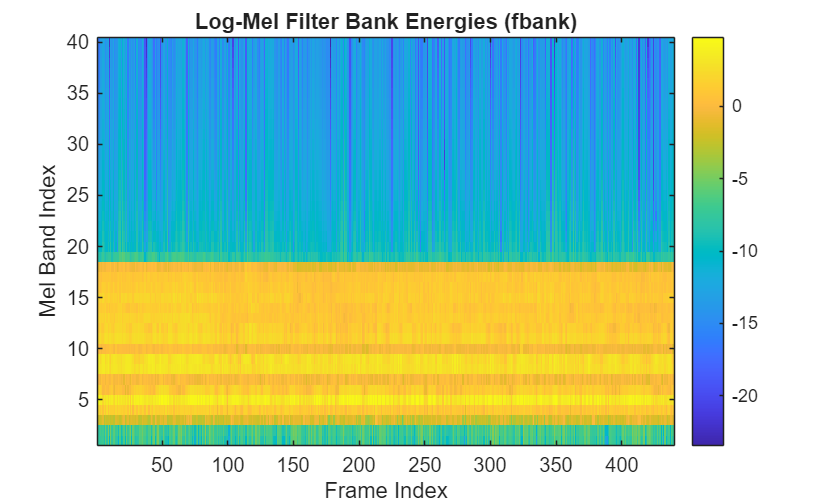


% Parameters
fs = 44100;
windowLength = 2048;
overlapLength = 1024;
fftLength = 2048;
numMelBands = 40;

% Preprocessing
x = mean(x, 2); % Mono
x = x / max(abs(x)); % Normalize
y = bandpass(x, [250 2500], fs); % Bandpass filter

% Framing
win = hamming(windowLength, 'periodic');
frames = buffer(y, windowLength, overlapLength, 'nodelay');
numFrames = size(frames, 2);

% Mel filter bank
melFB = designAuditoryFilterBank(fs, 'FFTLength', fftLength, 'NumBands', numMelBands);

% Initialize fbank matrix
fbank = zeros(numMelBands, numFrames);

for i = 1:numFrames
    frame = frames(:, i) .* win;
    spectrum = abs(fft(frame, fftLength)).^2;
    melEnergies = melFB * spectrum(1:fftLength/2+1); % Apply Mel filters
    fbank(:, i) = log(melEnergies + eps); % Log compression
end

% Plot fbank features
figure;
imagesc(fbank);
axis xy;
xlabel('Frame Index');
ylabel('Mel Band Index');
title('Log-Mel Filter Bank Energies (fbank)');
colorbar;